# **Excercise 1: K-means Clustering**

The aim of this first excercise is the clustering of real estate with the help of the k-means algorithm.

## ***Abstract***

*In this task, k-means clustering is applied to the house_data *dataset*. With the toolset, which was developed and tested in the first section, the clusters are formed and verified. The most meaningful results could be achieved by using only a subset of the features. Using these features, clustering into five groups gives the best results.*

% Initialization
clear ; close all; clc 

% Set default image size
set(groot,'defaultfigureposition',[600 250 400 250]) 

## **Develop toolset**

In the following sections we develop different functions that we need for K-means clustering. The different functions together form a toolset that allows us to cluster our dataset and determine the quality of the classification.

### Generate dev data

The data used for the development is generated using the function *generate2DData*. The generated data scatters around three points - for the classification therefore K = 3 is expected as the optimal number of clusters. Below the first five rows will be displayed:

% Generate dev data
X = generate2DData;

% Visualize 5 rows
disp(X(1:5, :))

   3.258894745572716   0.648729232772971
   3.623167748302477   3.177138162735628
   0.507947265174024   1.244860168179220
   3.653503424556078   2.114132542024851
   2.529436984901638   0.662594917999124



### Choosing the value of K

To get an idea of a suitable number of clusters, we use different methods to determine the optimal value of K.

#### Elbow method

In an "elbow" plot whe show the distortion for *2 ≤ k ≤ 20. *According to the plot, around three clusters would be optimal:

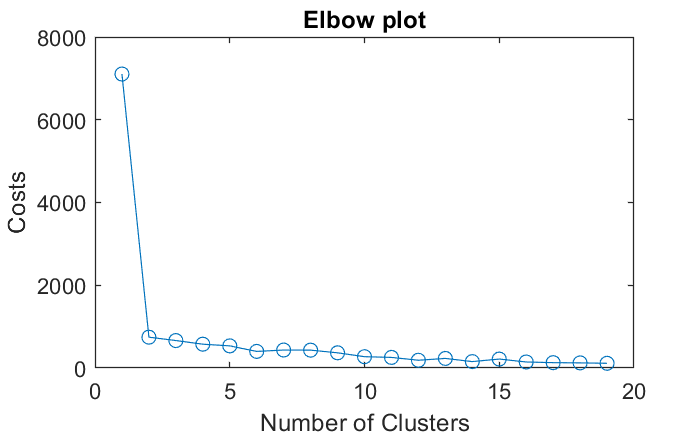

% Settings for running K-means
max_iters = 10;

% Visualize elbow plot
visualizeDistortion(X, max_iters)

#### Silhouette method

The silhouette plot provides a slightly more specific value. We calculate the silhouette values again for *2 ≤ k ≤ 20. *Again, we retrieve a value around three for the optimal number of clusters:

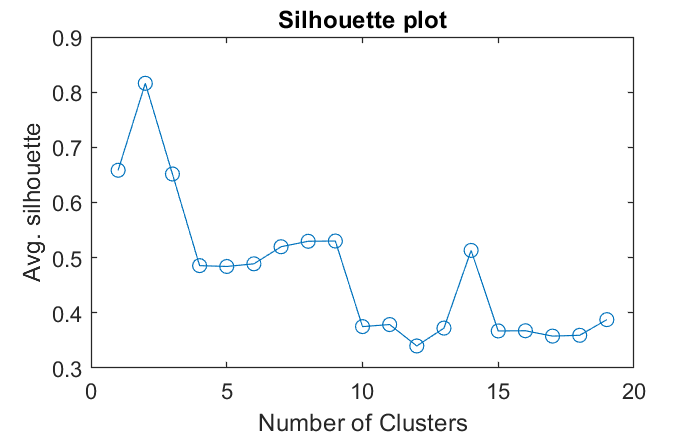

% Visualize silhouette plot
visualizeSilhouette(X, max_iters)

#### Gap statistic*

Another method is the gap statistics. We use the implementation of *evalclusters* to get an additional clue for an optimal k and to verify the functionality of the other two methods. In the plot, the calculated gap for three clusters is the highest - so our implementations seem to work.

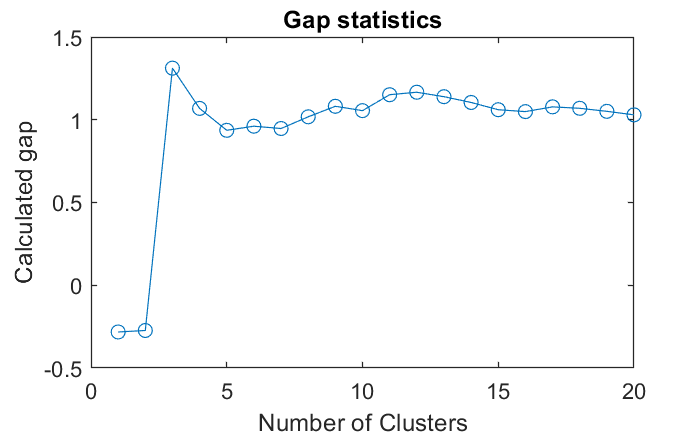

% Visualize gap statistics
visualizeGapStatistic(X)

### Initialize parameters

In the following sections, we set our K-means settings. From the previous section we know that a number of clusters of three is optimal. The initial centroids are initialized randomly multimple times (but at most 10 times) and should converge to an optimum within 10 steps:

% Settings for running K-means
K = 3; 
max_iters = 10;
max_inits = 10;

### Cluster data

As our parameters are initialized we can iteratively find the closest neighbours and compute the means to get a proper clustering. The process of clustering the data is shown in a plot. The course of the centroids approximation is thereby displayed as Xes, that are connected with coloured lines. We can see, that the Xes converge to the center of their groups:

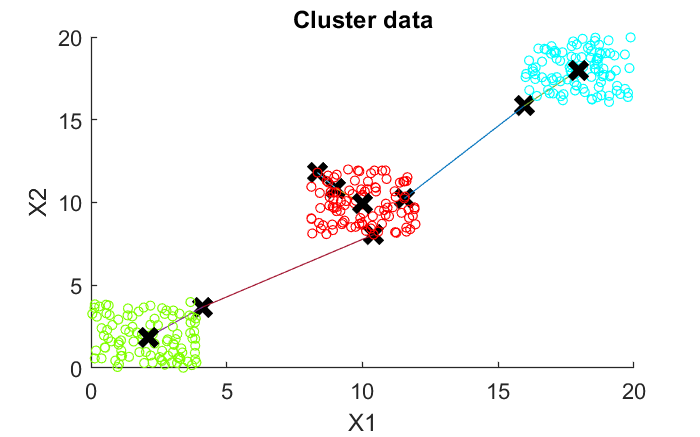

% Cluster data
[centroids, idx, J] = clusterData(X, K, max_inits, max_iters, true);

### Analyze clusters

Below we characterize the three clusters formed. We calculate variance, mean value, minimum and maximum for the two most similar features per cluster:

% Define column names
keySet = {1, 2};
valueSet = {'X1', 'X2'};
column_header = containers.Map(keySet,valueSet);

% Print cluster characteristics
% using top 2 similar features
n = 2;
characteriseCluster(X, idx, K, n, column_header)

Most similar features
Cluster 1, (0.33 amount of total data)
  - X1, (var: 1.2091, avg: 10.0178, min: 8.1147, max: 11.9519)
  - X2, (var: 1.3539, avg: 9.9132, min: 8.0619, max: 11.9963)
Cluster 2, (0.33 amount of total data)
  - X2, (var: 1.3426, avg: 1.8698, min: 0.0185, max: 3.9845)
  - X1, (var: 1.4115, avg: 2.1120, min: 0.0476, max: 3.8824)
Cluster 3, (0.33 amount of total data)
  - X1, (var: 1.0603, avg: 17.9715, min: 16.0046, max: 19.8746)
  - X2, (var: 1.1502, avg: 18.0041, min: 16.0783, max: 19.9748)


The following properties result from the values calculated above:

- **Cluster 1, 33%: **Medium values for X1 and X2 - well recognizable by average and min/max

- **Cluster 2, 33%: **Low values for X1 and X2 - again, well recognizable by average and min/max

- **Cluster 3, 33%: **High values for X1 and X2 as we can see on average and min/max

## **Cluster house data**

In this part of the excercise, the clustering will be applied to our house dataset.

### Load house data

The data used will be read from a given file *house_data*`.csv`. The description of the data and their origin is not part of this assignment. Below the first five rows will be displayed:

% Load house data
house_data = importHouseData('house_data.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long            municipality_name      zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ___________

As we calculate the distance to the centroids, we cannot consider categorical features (*e.g. municipality_name, object_type_name).* Various runs have shown that too many features have a negative impact on clustering: Initially all numerical features were used - but this led to contradictory results when looking at elbow, silhouette and gap statistics plot. The features were therefore reduced to those which had the greatest influence* on the cluster building when using all features. 

** Calculate features with the smallest variances per cluster, then those seven with the most occurrences in different clusters were selected.*

% Initialize variables
X = double(table2array(house_data(:, [{'price'},
                                      {'travel_time_private_transport'},
                                      {'number_of_workplaces_in_hectare'},
                                      {'number_of_workplaces_sector_1_in_hectare'},
                                      {'number_of_workplaces_sector_2_in_hectare'},
                                      {'number_of_workplaces_sector_3_in_hectare'},
                                      {'population_in_hectare'}])));

### Normalize features

The use of discrete features (e.g.* number_of_workplaces_in_hectare*) on a scale is limited because K-means assumes a continuous distribution here as well. To avoid this circumstance, we normalize the features.

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);

### Choosing the value of K

To get an idea of a suitable number of clusters, we plot the distortion for *2 ≤ k ≤ 20. *According to the elbow plot, we should chose ~6 as number of clusters.

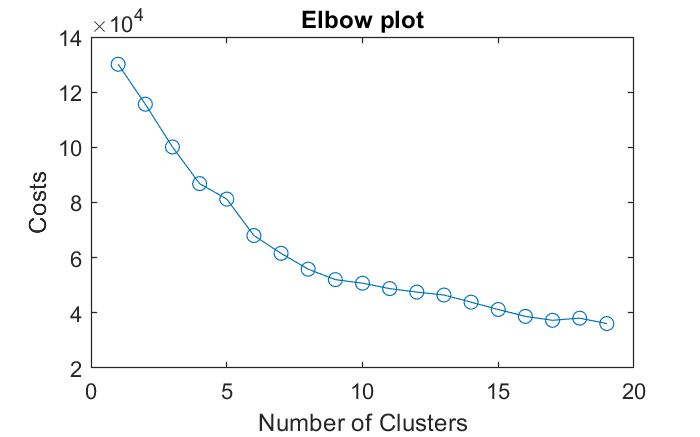

% Settings for running K-means
max_iters = 10;

% Visualize elbow plot
visualizeDistortion(X_norm, max_iters)

To check the value, we additionally calculate the silhouette plot. According to the plot a number of cluster < 3 would be optimal. But also four or five clusters provide a relatively good value. 

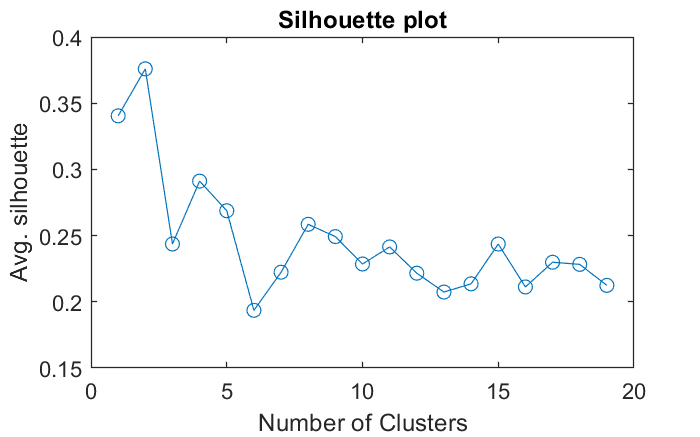

% Visualize silhouette
visualizeSilhouette(X_norm, max_iters)

### Initialize parameters

In the following sections, we set our K-means settings. Based on the previous plots, we use 5 as the number of clusters. The initial centroids are initialized randomly at most 10 times to prevent from chosing a local optima.

% Settings for running K-means
K = 5; 
max_iters = 20;
max_inits = 10;

### Cluster data

As our parameters are initialized we can iteratively find the closest neighbours and compute the means to get a proper clustering:

% Cluster data
[centroids, idx, J] = clusterData(X_norm, K, max_inits, max_iters, false);

### Visualize clusters 

Before we characterize the clusters, we plot the properties along their longitude and latitude. Although neither zipcode nor latitude or longitude have been used, geographical patterns (city, agglomeration and country) are recognizable on the map.

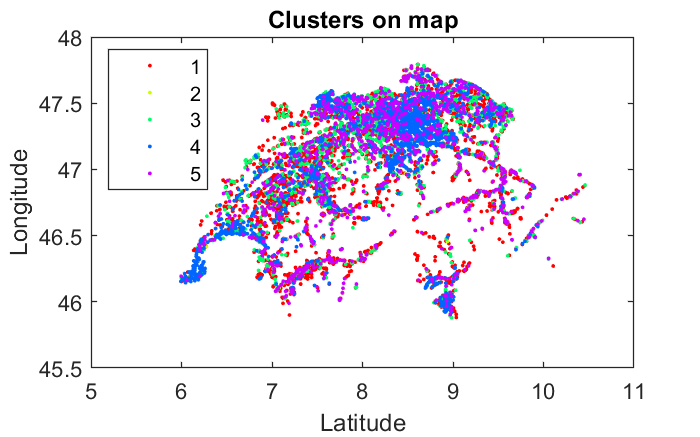

% Load geo information
X_geo = double(table2array(house_data(:, [{'lat'},
                                          {'long'}])));
    
% Plot map     
plotMap(X_geo, idx,'Clusters on map')

### Analyze clusters

Again calculate variance, mean value, minimum and maximum for the four most similar features per cluster:

% Define column names
keySet = {1, 2, 3, 4, 5, 6, 7};
valueSet = {'price',
            'travel_time_private_transport',
            'number_of_workplaces_in_hectare',
            'number_of_workplaces_sector_1_in_hectare',
            'number_of_workplaces_sector_2_in_hectare', %
            'number_of_workplaces_sector_3_in_hectare',
            'population_in_hectare'};
column_header = containers.Map(keySet,valueSet);

% Print cluster characteristics
% using top 4 similar features
n = 4;
characteriseCluster(X_norm, idx, K, n, column_header)

Most similar features
Cluster 1, (0.56 amount of total data)
  - number_of_workplaces_sector_1_in_hectare, (var: 0.0000, avg: -0.2418, min: -0.2418, max: -0.2418)
  - number_of_workplaces_sector_2_in_hectare, (var: 0.0000, avg: -0.5494, min: -0.5494, max: -0.5494)
  - number_of_workplaces_in_hectare, (var: 0.1593, avg: -0.2360, min: -0.6258, max: 2.9219)
  - number_of_workplaces_sector_3_in_hectare, (var: 0.1813, avg: -0.1646, min: -0.5805, max: 3.2051)
Cluster 2, (0.01 amount of total data)
  - price, (var: 1.2823, avg: 0.1512, min: -1.3660, max: 5.1384)
  - travel_time_private_transport, (var: 1.3281, avg: -0.4063, min: -1.4739, max: 4.5822)
  - number_of_workplaces_sector_1_in_hectare, (var: 1.6108, avg: 0.1256, min: -0.2418, max: 6.9914)
  - number_of_workplaces_sector_2_in_hectare, (var: 2.4245, avg: 1.6601, min: -0.5494, max: 13.2024)
Cluster 3, (0.21 amount of total data)
  - number_of_workplaces_sector_1_in_hectare, (var: 0.0000, avg: -0.2418, min: -0.2418, max: -0.2418)
  - nu

The following properties result from the values calculated above:

- **Cluster 1, 56%: **Cluster 1 is characterised by a low proportion of companies in the primary and secondary sector. Another striking feature of this cluster is the low number of workplaces in the immediate vicinity. On the map you can quickly see that these are mainly rural regions.

- **Cluster 2, 1%:  **Only a few objects belong to this cluster. These objects are expensive and close to private traffic. Another feature worth mentioning is the high number of jobs in the first two sectors in the area. A possible explanation for this could be that these are larger factories.

- **Cluster 3, 21%:  **Cluster 3 has a low proportion of companies in the primary sector - but a big number of workplaces in the industry. Since there are many jobs in the immediate surrounding, it is reasonable to assume that these are industrial areas.

- **Cluster 4, 17%: **In cluster 4, the low number of jobs in the first two sectors is noticeable. In the services sector, on the other hand, there are more jobs in this group. The map clearly shows that these are objects in urban areas (e.g. Zurich, Lucerne, Geneva).

- **Cluster 5, 5%:** In this cluster there is a big number of workplaces in primary sector. Moreover there are many workplaces in the immediate vicinity. Looking at the map, one can assume that these could be larger raw material extraction buildings, as the objects do not tend to be located in areas with a high population density.